# Annotated Isosurface Viewer

## Load in data (MRI)

s = load('mri.mat');
data = squeeze(s.D);

% Create isosurface
isovalue = 40;
[faces, vertices] = isosurface(data, isovalue);
voxel_size  = [1 1 3];
vertices    = vertices .* voxel_size;
vertexNormals = isonormals(data,vertices);

% Place into an IsosurfaceModel
isoModel = wt.model.IsosurfaceModel(...
    'Faces',faces,...
    'Vertices',vertices,...
    'VertexNormals',vertexNormals);

## Create the widget

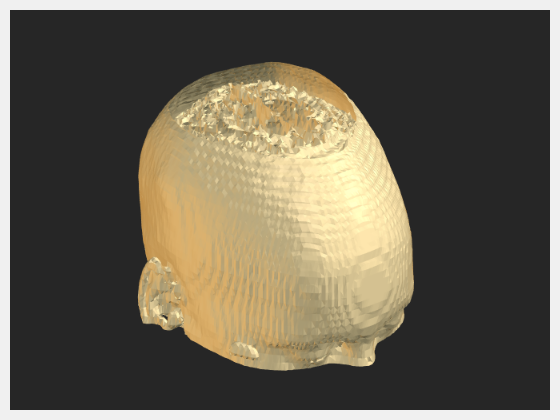

f = uifigure;
movegui(f,'northwest')
g = uigridlayout(f,[1 1]);
w = wt.AnnotatedIsosurfaceViewer(g);
w.IsosurfaceModel = isoModel;

## Add Points Annotation

thisPoints = [
   84.1572   31.2435   80.9678
   47.4634   45.7015   80.9667
   46.5614   77.8666   80.9756
    ];
 thisColor = [.5 .7 .3];
 thisAlpha = .7;
a1 = wt.model.LineAnnotation(...
    'Name','Line 1',...
    'Points',thisPoints,...
    'Color',thisColor,...
    'Alpha',thisAlpha,...
    'IsVisible',true);

w.addAnnotation(a1);

## Add Plane Annotation

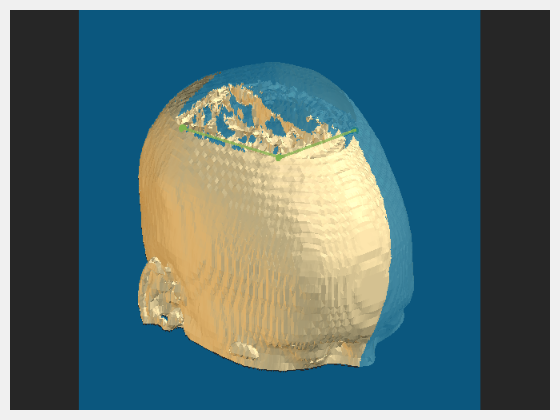

thisPoints = [
   110.6 67.67 77.12
   17.41 72.61 38.27
   20.97 64.07 4.049
   ];
thisColor = [0 0.6000 1];
thisAlpha = .7;
a2 = wt.model.PlaneAnnotation(...
    'Name','Plane 1',...
    'Points',thisPoints,...
    'Color',thisColor,...
    'Alpha',thisAlpha,...
    'IsVisible',true);

w.addAnnotation(a2);

## Labeling Annotations Using the Mouse

You can interactively add annotations from your app. These code examples show how to implement this:

### Begin a new annotation

Add a new annotation programmatically by first creating and configuring the annotation model. Then, add it to the viewer using the widget's `addInteractiveAnnotation` method:

Add points by clicking on the surface. If you need to zoom / pan / rotate, you can enter those modes from the toolbar but turn them off again to continue adding points.

There are several similar types of annotations applicable to a 3D isosurface.  They are defined by a set of points:

- `PointsAnnotation` - just a set of points

- `LineAnnotation` - a set of connected points

- `PolygonAnnotation` - a closed shape of connected points

- `PlaneAnnotation` - a set of (typically 3) points defining a 3D plane.

#### Mouse Interactions

While editing one of these annotation types, the mouse buttons behave this way:

- Left mouse button - add point

- Left button drag - move point

- Right mouse button - delete point

- Double-click left button - finish editing

### Finishing edits

When finished making an annotation, you can finish editing it programmatically using:

### Removing an annotation

You can remove an annotation using:

### Editing an existing annotation

You can continue editing an existing annotation using:

*Copyright 2018-2021 The MathWorks, Inc.*